# OvalRoverSimulation.mlx is a simulation of a planetary rover

This code simulates a wheeled autonomous planetary rover performing multiple missionas on the olin roval.

    - It takes a desired location waypoints as inputs

    - It delivers a moving map simulation of rover transersing the Oval as an output

Sign your name here and give the creation date and revision number

close all;
clc        % clear commmand window
clear      % clear MATLAB workspace

## Set up robot control system (code that runs once)

img = imread('TestPool.png'); % load oval image 
grayimage = im2gray(img);       % convert to grayscale
bwimage = grayimage < 0.5;      % convert to black and white

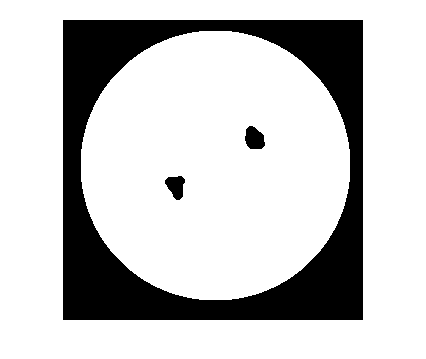

SE = strel("disk",15);
map = imclose(bwimage, SE);
map = imcomplement(map);

imshow(map)

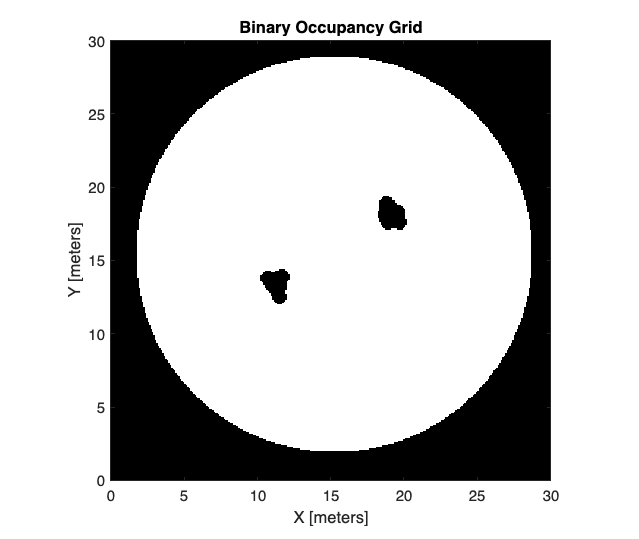


MapOfOval = binaryOccupancyMap(bwimage,10); % convert to a binary occupancy map in meters
show(MapOfOval);

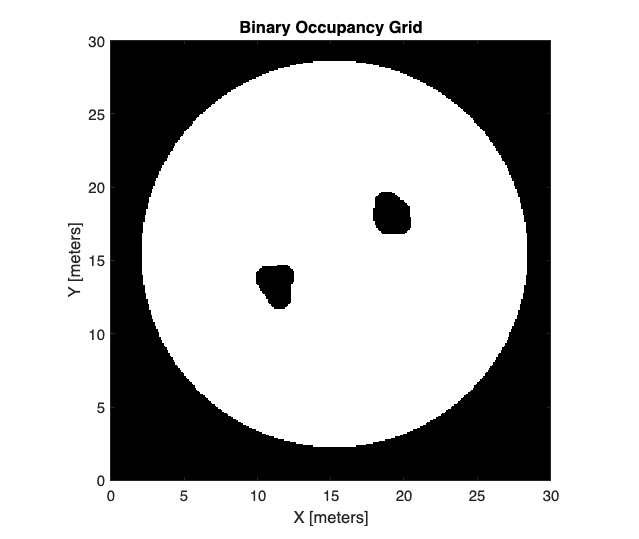

% Inflate the map wit the robot rober size, so robot can be treated as a
% point. Assume robot rober is a 0.25m long bow to stern
MapOfOvalInflated= copy(MapOfOval); % make a copy to save original data
inflate(MapOfOvalInflated,0.25); %dilate map to accomendate robot size
% show(MapOfOvalInflated)

testTrack = figure('name','testTrackMap','NumberTitle','off','Visible','on')

testTrack =   Figure (12: testTrackMap) with properties:

      Number: 12
        Name: 'testTrackMap'
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


figure(testTrack)
    show(MapOfOvalInflated);
    grid on;
    grid minor;
    

Create a IR based map of world (to be filled in as Rober drives around Oval)

% Create an empty map of the same dimensions as the test track map

[mapdimx, mapdimy] = size(bwimage)

mapdimx = 300

mapdimy = 300

sharpIRMap = binaryOccupancyMap(mapdimx, mapdimy, 10, 'grid')

sharpIRMap =   binaryOccupancyMap with properties:

   mapLayer Properties
              LayerName: 'binaryLayer'
               DataType: 'logical'
           DefaultValue: 0
    GridLocationInWorld: [0 0]
      GridOriginInLocal: [0 0]
     LocalOriginInWorld: [0 0]
             Resolution: 10
               GridSize: [300 300]
           XLocalLimits: [0 30]
           YLocalLimits: [0 30]
           XWorldLimits: [0 30]
           YWorldLimits: [0 30]



% Create a free floating figure for map to deal with livescript update
% problem
roversharpIRScan = figure('name','RoverSharpIRScan','NumberTitle','off','Visible','on');
% figure(roversharpIRScan)
%     show(sharpIRMap);
%     grid on;
%     grid minor;


Create a differential driver robot rover (thus model taks robot vehicle speed and heading for inputs)

diffDriveRover = differentialDriveKinematics('VehicleInputs','VehicleSpeedHeadingRate');

Create a pure pursuit rover controller (this controller generates the robots speed and hearing needed to follow a desired path, set desired linear velocity and max angular velocity in m/s and rad/s.

RoverController = controllerPurePursuit('DesiredLinearVelocity',2,'MaxAngularVelocity',3);

Create 360 degree LIDAR range sensor for your rover

- Create a sensor with a max range of 40 meters. This sensor simulates

- range readings based on a given pose amd map. The Olin Oval map is used

- with this range sensor to smulate collecting sensor readings in an unknown environment

- its a little hard to find documentation on range Sensor function, so right click on it and choose "help" or f1

sharpIRPod = rangeSensor;        % create a rangeSensor system object see help for info
sharpIRPod.Range = [0.1,10];     % sets minimum and maximum range of sensor
sharpIRPod.HorizontalAngle =  [-pi/2, pi/2];
sharpIRPod.HorizontalAngleResolution = 0.628318;
testPose = [20 23 pi/2];    % sets an inital test pose for IR

% Plot the ttest spot for lidat scan on the reference Olin Oval Map
figure(testTrack)
hold on 
plot(20,23,'r*');
hold off

% generate a IR test scan from test position
[ranges, angles] = sharpIRPod(testPose, MapOfOvalInflated);
scan = lidarScan(ranges,angles);


% Visualize the test lidat scan data in robot coordinate system.
% Create a new free-standing figure to display the local lidar data, rover
% at center

localSharpIRPlot = figure('Name','localSharpIRMap','NumberTitle','off','Visible','on')

localSharpIRPlot =   Figure (14: localSharpIRMap) with properties:

      Number: 14
        Name: 'localSharpIRMap'
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


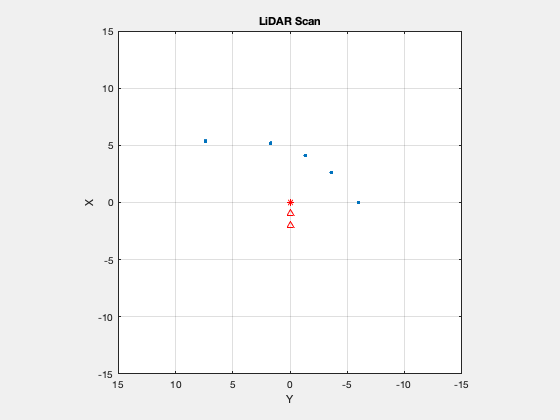

figure(localSharpIRPlot)
plot(scan)
axis([-15 15 -15 15]);
hold on;
plot(0,0,'r*')
plot(-1,0,'r^')
plot(-2, 0, 'r^')
hold off;

create a test path to drive through the map for gathering range sensor readings.

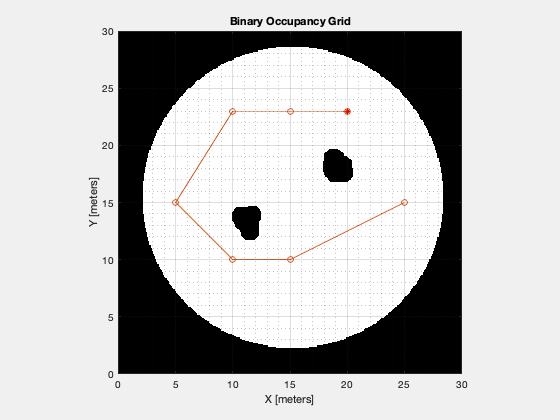

path = [ 20 23; 15 23; 10 23; 5 15; 10 10; 15 10; 25 15];

% Plot the path on the reference map figure
figure(testTrack) %select OvalTrackMap
hold on
plot(path(:,1),path(:,2),'o-');%plot path on it
hold off;

Use this test path as the set of waypoints the pure purtsuit controller will follow:

RoverController.Waypoints = path; % set rover waypoints

Set the initial pose and final goal WayPoint location based on the path. Create global variables for storing the current pose and an index for tracking the iterations.

initRoverPose = [path(1,1) path(1,2), pi/2];     % store initial location and orieatation of the rover
goalWayPoint = [path(end,1) path(end,2)]';       % PATH END WAYPOINT
sampleTime = .1;                               % sample time (s)
t = 0:sampleTime:100;                      % time array
robotPoses = zeros(3,numel(t));
robotPoses(:,1) = initRoverPose';
r = rateControl(1/sampleTime);
reset(r)

ready to run robot, ask operator if the are set and suggest they move plots to a visable position

runRover = input('Ready to run rover? Please arrange yout data plot figures for clear visibility, then enter 1 or 0 and hit enter');
clc


## Run robot control loop (code that runs over and over)

controlIndex = 1;    % create a robot loop control

   -1.0000
    1.0000
    1.0000



ans =      1
     2


while(controlIndex < numel(t))  %loop for a number of elements in t
    position = robotPoses(:,controlIndex)';
    roverLocation = position(1:2);
    % End loop if rover has reached goal waypoint within tolerance of 1.0m
        dist = norm(goalWayPoint'- roverLocation);
        if(dist<1.0)
            disp("Goal position reached!");
            break;
        end
    % SENSE: collect data from robot IR sensors
    [ranges, angles] = SENSE(position, MapOfOvalInflated, sharpIRMap,roversharpIRScan , localSharpIRPlot, sharpIRPod);
    
    % THINK: compute what robots should do next
    [roverX, roverY, robotPoses] = THINK(robotPoses, diffDriveRover,RoverController, sampleTime, controlIndex);

    % ACT: command robot actuators
    ACT(roverX,roverY,testTrack);

    controlIndex = controlIndex+1;  % increment control loop index
    waitfor(r); % wait for loop cycle to complete

end
beep %give sudio indication waypoint is reached

transformCoord([2;1;pi/2],[1;1])

clean shut down

## Robot Functions (store this code local functions here)

% function CONTROL_LOOP_OUTPUT(time)
%     disp('robot runing, cntrl-c to stop')
%     fprintf('The loop time is %d, \n', time);
% end

In practive for modularity, readability and longitevity, your main robot code should be as brief as possible and the bulk of the work should be done by functions

Sense Functions (store all Sense related local functions here)

function [ranges, angles] = SENSE(position, mapOfTrack, blankLidarMap,fig_lidarMap,fig_localLidarPlot,lidar)

% SENSE scans the reference map using the range sensor and the current
% pose.
% This simulates normal range readings for driving in an unknown
% environment
% Update the lidar map with the range readings
% inpus are rover position, mapOfTrack, lidarMap, figure to plot global
% lidar, figure to plot local lidar, sensor name outputs are lidar ranges
% and angles in local coordinate system

    [ranges, angles] = lidar(position, mapOfTrack);                         
    scan = lidarScan(ranges, angles);
    validScan = removeInvalidData(scan, "rangeLimits",[0,lidar.Range(2)]);
    insertRay(blankLidarMap, position, validScan, lidar.Range(2));

    figure(fig_lidarMap);
        hold on;
        show(blankLidarMap);
        grid on;
        grid minor;
        hold off;
   

    figure(fig_localLidarPlot);
    plot(scan);
    hold on;
    plot(0,0,'r*');
    hold off;
    workspace;
end

Think Functions (store all think related local funtions here)

function [roverX, roverY, poses] = THINK(poses, diffDrive, ppControl, sampleTime, loopIndex)
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef, wRef] = ppControl(poses(:,loopIndex));

    % Perform forward discrete integration step
    vel = derivative(diffDrive, poses(:,loopIndex), [vRef, wRef]);
    poses(:,loopIndex+1) = poses(:,loopIndex) + vel*sampleTime;

    %update rover location and pose
    roverX = poses(1,loopIndex+1);
    roverY = poses(2,loopIndex+1);

end

Act Functions (store all Act related functions here)

function ACT(roverX, roverY, fig_testTrack)
    figure(fig_testTrack)
    hold on
    plot(roverX,roverY,'b*');
     hold off
end


Function to Transform robot coordinate to world coordinate

function world_coord = transformCoord(robotPose, robot_coord)
    theta = robotPose(3);
    rotation_mat = [cos(theta), -sin(theta); sin(theta) cos(theta)];
    translation_mat = [1 0 robotPose(1); 0 1 robotPose(2); 0 0 1];
    rotated_pose = rotation_mat*robot_coord;
    rotated_pose(3) = 1;
    disp(rotated_pose);
    world_coord = translation_mat * rotated_pose;
    world_coord = world_coord([1 2]);
end